# Exercise 3: Track Multiple Pieces of Space Debris in 3D

## What is "Tracking"?

The following flowchart shows the basic functional actions that a tracker performs.

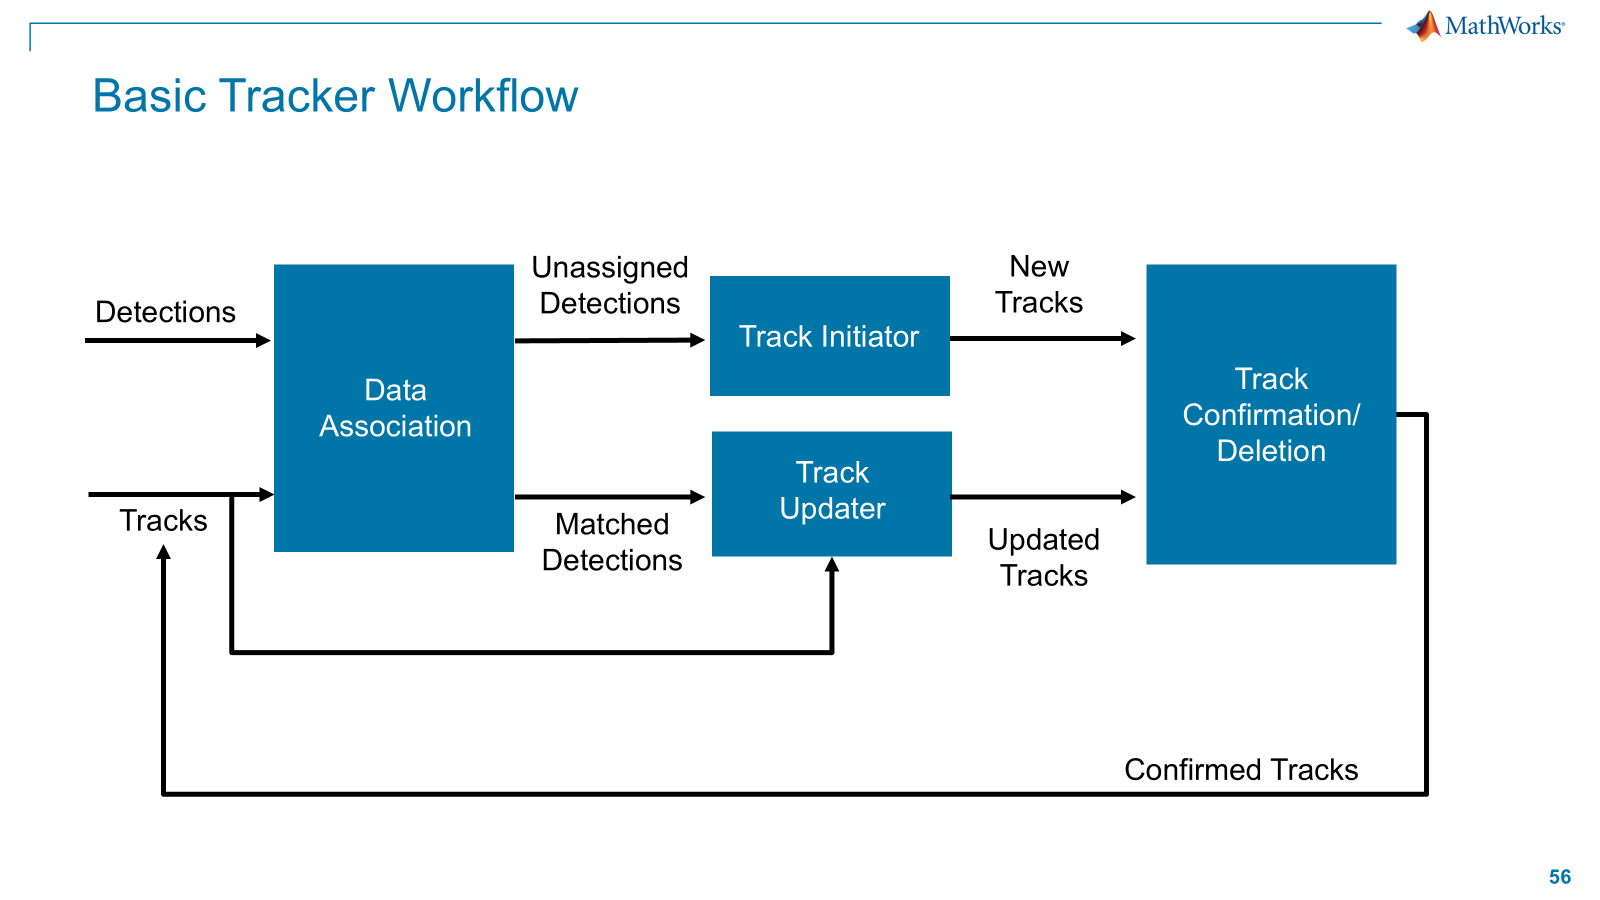

## Define Tracker and Incorporate Filter

Let's briefly look at the anatomy of a **tracker** within MathWorks Tools. Different System Objects are used in the Sensor Fusion and Tracking toolbox to accomplish the tracking task. The **tracker** object holds the overall tracking algorithm including the track maintenance tasks (initialization, association, formation, and termination) and the **initialization object **holds the filter and the initial state data itself.

A simplified view of the components of a tracker as defined within Sensor Fusion and Tracking Toolbox is below. If you are interested in more of the specifics of building trackers, and the components that you can change to match your application, please see this [documentation page](https://www.mathworks.com/help/fusion/ug/introduction-to-multiple-target-tracking.html).

When performing tracking in MATLAB, we pass detections to the tracker, which performs track maintenance tasks and leverages the filter and initial state to update the track.

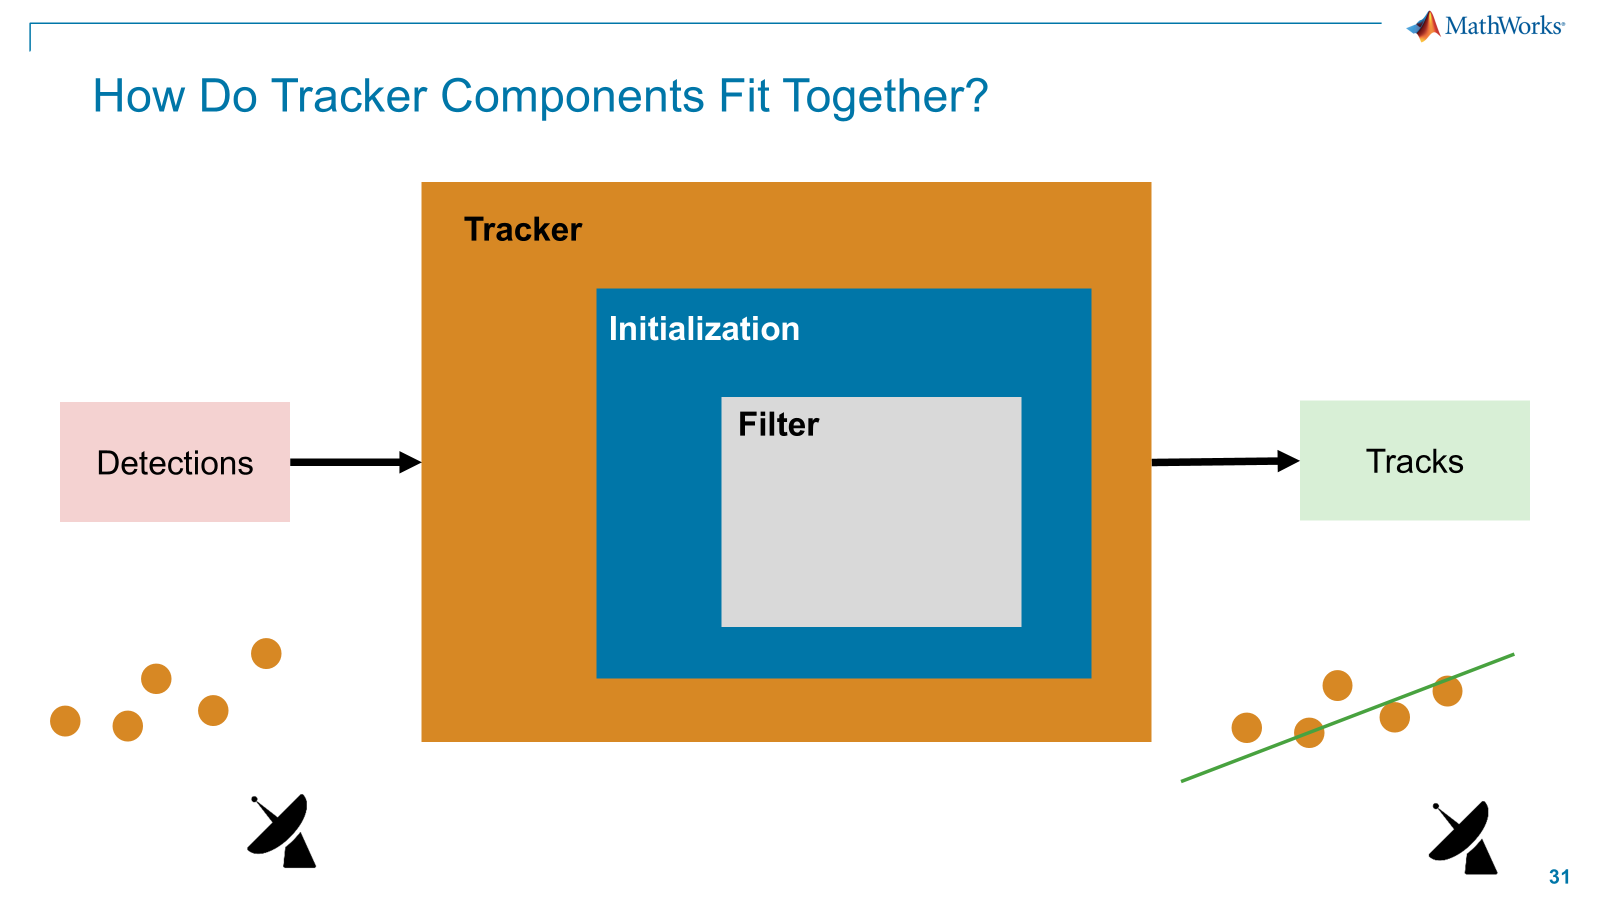

For more information on how tracking filters work, please check out the flowchart at this documentation page: [Introduction to Estimation Filters - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2024b/fusion/ug/introduction-to-estimation-filters.html?searchPort=58770#mw_0cb4470b-522e-463f-aecd-9842f4ee6eed)

## Exercise 3a: TrackerGNN with Filter Settings from Exercise 2

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all;

Let's load in our truth and detection data from the previous example:

load('SpaceDebris4Targets_New.mat')

Let's begin by defining a simple tracker and incorporate the filter settings that we explored in the previous example. Define the tracker using a "trackerGNN" filter, defaults to filterInitializationFcn "`initcvekf"` with default values`.`

Directions:

Instantiate a tracker using the "trackerGNN" function and assign it to a variable "tracker".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerGNN" in the Command Window to find the documentation page for this function
tracker = trackerGNN;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Above runs with default filter inputs, let's make updates to the filter
% to accomodate what we learned in previous exercise:
knownVelo = 7e3; % m/s
detectionMeasurementNoise = objDet{1}.MeasurementNoise;
% Give them this line:
tracker.FilterInitializationFcn = @(det) initFilter(det,knownVelo,detPos,detectionMeasurementNoise); 
tracker.AssignmentThreshold = 100;

## Plot Detections and Corresponding Tracks

Loop through the detection data via the time vector to plot detections and tracks as the target moves through the space near the radar sensor. The code below is based on the .M file exported from the trackingScenarioDesigner App. 

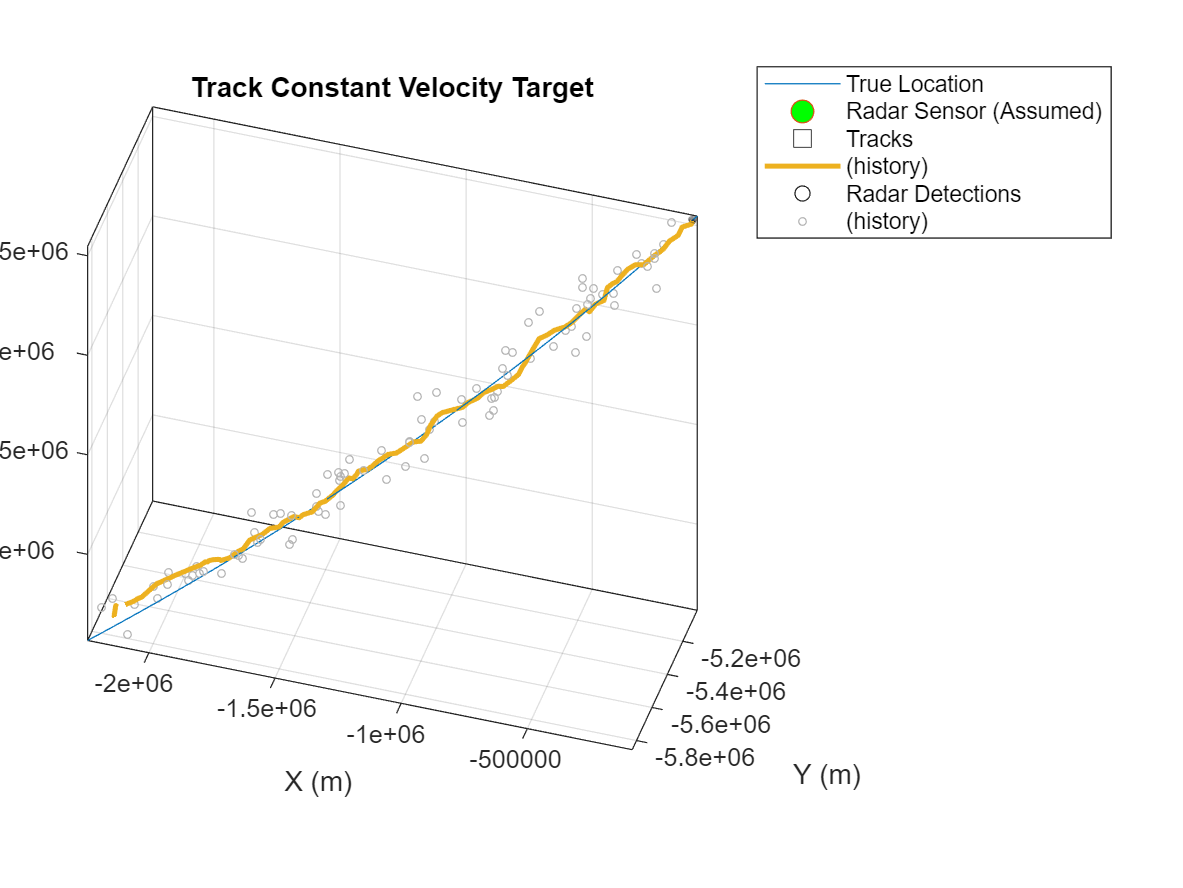

% Preallocate tracks vector
tracks = cell(length(time),1);
dist = zeros(length(time));
reset(tracker)

% Scenario:
f=figure; hold on;
tp = theaterPlot('Parent',gca);
[labels,tp] = createScenario(truthPos,tp,f); % Give them this line

% Create a trackPlotter and detection plotter
tracksPlot = trackPlotter(tp,'DisplayName','Tracks',ColorizeHistory="on",ConnectHistory="on");
radarPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Radar Detections');

% Main Simulation Loop
for n = 1:length(time)
    
    % Plot Position of Current Detection each loop - 
    % "Plot as sensor detects target" fashion
    plotDetection(radarPlotter,detPos(:,n)')
    
    
    % Track Object using objectDetections 
    tracks{n} = tracker(objDet{n},time(n));
    
    % Obtain Locations from Tracks
    [pos, posCov] = getTrackPositions(tracks{n},'constvel');

    % Use trackPlotter to plot Track Location
    tracksPlot.plotTrack(pos,posCov,string([tracks{n}.TrackID]))
    
    % Pause during loop to watch tracker progress during visualization
    pause(0.1)
end

Above, we see that our tracker is able to track the single target relatively well. Let's see how it does with multiple targets.

## Exercise 3b: Test Our Tracker on Multiple Targets

Now that we've established that our tracker and filter combination works well with the single representative target, let's incorporate multiple targets and test our tracker in the trackingGlobeViewer.

Load dataset for multiple targets

load('SpaceDebris5Targets.mat')

Build trackingGlobeViewer scenario

% Format figure window for ease of use (consider dropping):
h = uifigure;

% Configure Tracker
% Use detection data to estimate variances and process noise
tracker = trackerGNN('FilterInitializationFcn',@(detection)initFilterMulti(detection,noisyDets),AssignmentThreshold=100);

mapOrigin = [42.39423231362 -70.95934958874 0];
gViewer = trackingGlobeViewer(h,'ReferenceLocation',mapOrigin);

Coding Directions:

Create a scene for the tracker to be tested in. Use the "trackingScenario" function with an earth centered frame and pass the update rate and stoptime to the function. Variables for this settings were loaded in the MAT file above. The update rate is stored in the variable "UpdateRate" and the stop time is stored in the variable "stopTime".

(Hint: you will need to use the "IsEarthCentered", "UpdateRate", and "StopTime" name-value pairs to configure the settings of the trackingScenario)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackingScenario" in the Command Window to find the documentation page for this function
% Create scenario based on sample rate and stoptime of dataset
scene = trackingScenario('IsEarthCentered',true,'UpdateRate', UpdateRate,'StopTime',stopTime);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Adjust the camera to view the area of interest:
campos(gViewer,[37.2337 -91.6920 5.5488e+06]);

% Plot truthTrajectory for reference:
plotTruthTraj(gViewer,trajectoryCell)

Run simulation loop

% Run tracker on loaded detection data
count=0;
restart(scene)
reset(tracker)
%rec = record(scene);
% Run Simulation Loop
while advance(scene)

    count = count+1;
    time = scene.SimulationTime;

    % Force detection time to be less than or equal to scenario time
    % (required by tracker)
    if noisyDets(count).Time > time
        time = noisyDets(count).Time;
    end

    % Pass just trajectories:
    trackCount = [count count+100 count+200 count+300];
    [tracks,~,~,info] = tracker(noisyDets(trackCount),time);

    % Generate tracks and truths using simulation
    truths = getTruths(trajectoryCell,time);

    % Plot Detection
    plotDetection(gViewer,noisyDets(trackCount),"ECEF");
    storeDets(count,:) = noisyDets(count).Measurement;

    % Pause so you can visualize detections as they are plotted
    pause(0.1)

    % Plot Tracks
    plotTrack(gViewer,tracks,"ECEF");
end

# **Takeaways**

We have established our estimation filter and implemented it as part of our tracking algorithm using a basic tracker: trackerGNN. We then used the same approach to track four satellites passing over the US using trackingGlobeViewer to view our tracking progress in a 3D Earth-Centered view.

## **HELPER FUNCTIONS**

**createScenario**

function [labels,tp] = createScenario(truthPos,tp,f)
% Plot noisy and truth trajectory data
%clf
%f=figure;
f.Position = [1e3 818 560*2 420*2];
truePos = plot3(truthPos(1,:),truthPos(2,:),truthPos(3,:)); hold on;

% Plot radar sensor location:
pos_radar = plot3(0,0,0);
pos_radar.Marker = 'o';
pos_radar.MarkerSize = 10;
pos_radar.MarkerFaceColor = 'g';
pos_radar.LineStyle = 'none';
legend([truePos,pos_radar],'True Location','Radar Sensor (Assumed)')
title('Track Constant Velocity Target')
grid on 
box on
axis vis3d equal
xlabel('X')
ylabel('Y')
zlabel('Z')
view(17,41)

% Setup Viewer and Plotters:
%tp = theaterPlot('Parent',gca);
minVals = min(truthPos');
maxVals = max(truthPos');
% tp.XLimits = [-2.7776e+04 1.5037e+04];
% tp.YLimits = [-1.3634e+04 2.9844e+04];
% tp.ZLimits = [0 6.7006e+03];
tp.XLimits = [minVals(1) maxVals(1)];
tp.YLimits = [minVals(2) maxVals(2)];
tp.ZLimits = [minVals(3) maxVals(3)];

labels = {'Current Radar Detection'};
end

**initFilter**

function filter = initFilter(detection,knownSpeed,detPos,detectionMeasurementNoise)
filter = initcvekf(detection);

% Adjust the state so the position is close to the detection and the
% velocity starts at zero (this will allow for the filter to dictate the
% direction via the sign)
filter.State([2 4 6]) = 0; % Set Initial Velocities to zero
filter.State([1 3 5]) = detPos(:,1); % Set Initial position to initial detected position 

% Set state covariance matrix diagonal according to the measurement noise and the known
% speed:
filter.StateCovariance = blkdiag(detectionMeasurementNoise(1),knownSpeed^2/3,detectionMeasurementNoise(1),knownSpeed^2/3, detectionMeasurementNoise(1),knownSpeed^2/3);

% Set filter measurement noise according to the detection measurement noise
filter.MeasurementNoise = detectionMeasurementNoise;

% Decrease Process Noise, indicating stronger confidence in Measurements
% This is set lower than Exercise 2 because in this example, we are working
% in 3D instead of 2D
filter.ProcessNoise = eye(3)*1e-4;

end


**initFilterMulti**

Relevent Reminders:

Uniform Distribution (a,b) for 1D:


$$f(x) = \frac{1}{b-a}$$


$x$ = $\left\lbrack \begin{array}{c}
p\\
v
\end{array}\right\rbrack$


$$Expected Value(mean) =  \mu = \frac{a+b}{2}$$



$$Variance  = \sigma^2 = \frac{(b-a)^2}{12}$$


$Std. Dev = \sigma$ =  $\sqrt\frac{(a-b)^2}{12}) $=$\sqrt{\sigma^2}
$

function filter = initFilterMulti(detection,noisyDets)

filter = initcvekf(detection);

% Estimate Velocity and Acceleration from Detection Data:
% Velocity Estimate
deltaPos = norm(noisyDets(2).Measurement - noisyDets(1).Measurement);
deltaT = (noisyDets(2).Time - noisyDets(1).Time);
velocityEst = deltaPos/deltaT;

% Acceleration Estimate
deltaPos2 = norm(noisyDets(4).Measurement - noisyDets(3).Measurement);
deltaT2 = (noisyDets(4).Time - noisyDets(3).Time);
velocityEst2 = deltaPos2/deltaT2;
aveTime1 = (noisyDets(2).Time + noisyDets(1).Time)/2;
aveTime2 = (noisyDets(4).Time + noisyDets(3).Time)/2;
deltaTAve = aveTime2-aveTime1;
accelerationEst = (velocityEst2-velocityEst)/deltaTAve;

% State Covariance
% 2,4,6 = (Max Velocity^2)/12 -> show the tracker how fast the target can move, default (100) is way off
% Find indices for the diagonal
[m, n] = size(filter.StateCovariance); 
diagIndx = 1:(m+1):min(m*n, m*n); % Full diag
velocityIndx = diagIndx(2:2:size(diagIndx,2)); % indices for velocity on the diagonal
filter.StateCovariance(velocityIndx) = ones(size(velocityIndx))*velocityEst^2/12; % Assume a uniform distribution intially (set velocities to variance)

% Process Noise
%ScaleValue = 1e-3; % This is too small - (Max Acceleration^2)/12 of targets (delta Velocity/ deltaT between 2 points)
%filter.ProcessNoise = ScaleValue*eye(size(filter.ProcessNoise));
filter.ProcessNoise = accelerationEst^2/12 * eye(size(filter.ProcessNoise)); % Assume a uniform distribution intially (set Acceleration to variance)
%disp('check')
end


**runDataLoop**


function runDataLoop(tracker,detPos,objDet,radarPlotter,tracksPlot,truthPos,time)
% Clear plotters
clearData(tracksPlot)
clearData(radarPlotter)

% Preallocate tracks vector
tracks = cell(length(time),1);
dist = zeros(length(time));

for n = 1:length(time)
    
    % Plot Position of Current Detection each loop - 
    % "Plot as sensor detects target" fashion
    plotDetection(radarPlotter,detPos(:,n)')
    % plotDetection(radarPlotter,detPos(:,n)',labels) % Include a "current
    % detection" label if you want
    hold on;
    
    % Track Object using objectDetections 
    tracks{n} = tracker(objDet{n},time(n));
    
    % Obtain Locations from Tracks
    [pos, posCov] = getTrackPositions(tracks{n},'constvel');

    % Use trackPlotter to plot Track Location
    tracksPlot.plotTrack(pos,posCov,string([tracks{n}.TrackID]))
    
    % Calculate Distance between track and true position
    if isempty(pos) || size(pos,1) ~=1
        dist(n)=0;
    else
        dist(n) = vecnorm(pos' - truthPos(:,n), 2, 1); % Euclidean distance from true position
    end

    % Pause during loop to watch tracker progress during visualization
    pause(0.25)
end
end


**getTruths**

function truths = getTruths(trajCell,time)
truths = [];
for i = 1:length(trajCell) %
    traj = trajCell{i};
    id = i;
    [pos, orient, vel, acc, angVel] = lookupPose(traj,time,'ECEF');
    %ecef = lla2ecef(lla)
    thisTruth = assembleTruth(trajCell,id,pos,orient,vel,acc,angVel);
    truths = [truths;thisTruth];    %#ok<AGROW>
end
end

**assembleTruth**

function truth = assembleTruth(obj,id,pos,orient,vel,acc,angVel) %#ok<INUSL>
if isnan(pos)
    pos = {};
    orient = {};
    id = {};
    vel = {};
    acc = {};
    angVel = {};
end
truth = struct('PlatformID',id,...
    'Position',pos,...
    'Velocity',vel,...
    'Orientation',orient,...
    'Acceleration',acc,...
    'AngularVelocity',angVel);

end


**plotTruthTraj**

function plotTruthTraj(gViewer,trajectoryCell)
% Define colors for plotting:
pColor=[1 0 0;
    0 1 0;
    0 0 1;
    0 0.5 0.5];

for i = 1:length(trajectoryCell)
    plotTrajectory(gViewer,trajectoryCell{i},Color=pColor(i,:))
end
end